# The goal for this version is to modify presynaptic cell, to fix the numbers

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo052921/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...currentVec(2)^2
    N_E,NnE,Size_E,...
    Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 14.204889 seconds.



C_EI_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 6.698061 seconds.



C_IE_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_E,NnE,Size_E,...
    Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 8.241535 seconds.



C_II_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.169554 seconds.


## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

Elapsed time is 5.635621 seconds.
Elapsed time is 8.310682 seconds.
Elapsed time is 11.010403 seconds.
Elapsed time is 13.651142 seconds.
Elapsed time is 16.384323 seconds.
Elapsed time is 19.115911 seconds.
Elapsed time is 21.725828 seconds.
Elapsed time is 24.553735 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

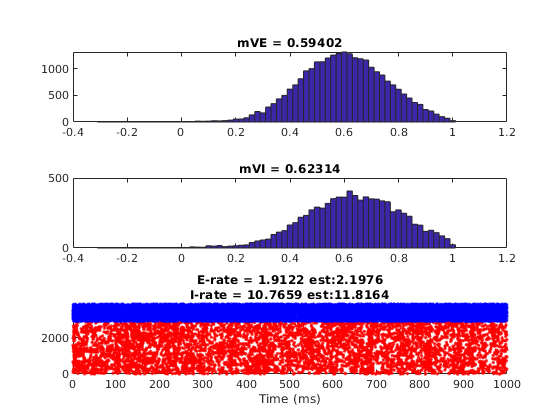

Elapsed time is 28.717629 seconds.
Elapsed time is 31.591144 seconds.
Elapsed time is 34.491885 seconds.
Elapsed time is 37.388463 seconds.
Elapsed time is 40.202388 seconds.


%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
%   R = sparse(A,floor(Times/dt)+1,ones(size(A)),N,length(t));

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_T' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 20.3765

FrINow = 74.9728

Elapsed time is 2.504302 seconds.


SampleInd = 3

FrENow = 14.7478

FrINow = 64.9624

Elapsed time is 4.193642 seconds.


SampleInd = 4

FrENow = 16.9060

FrINow = 70.2255

Elapsed time is 6.537426 seconds.


SampleInd = 5

FrENow = 15.8718

FrINow = 68.3778

Elapsed time is 8.201279 seconds.


SampleInd = 6

FrENow = 17.2588

FrINow = 72.0083

Elapsed time is 10.530760 seconds.


SampleInd = 7

FrENow = 15.7560

FrINow = 68.5837

Elapsed time is 12.140724 seconds.


SampleInd = 8

FrENow = 16.1629

FrINow = 69.1456

Elapsed time is 14.340255 seconds.


SampleInd = 9

FrENow = 16.0052

FrINow = 68.9328

Elapsed time is 15.999070 seconds.


SampleInd = 10

FrENow = 17.5652

FrINow = 72.4361

Elapsed time is 18.306454 seconds.


SampleInd = 11

FrENow = 15.5434

FrINow = 68.0911

Elapsed time is 19.901028 seconds.


SampleInd = 12

FrENow = 16.3077

FrINow = 70.0613

Elapsed time is 22.068778 seconds.


SampleInd = 13

FrENow = 16.1652

FrINow = 69.5410

Elapsed time is 23.736834 seconds.


SampleInd = 14

FrENow = 16.8953

FrINow = 71.5690

Elapsed time is 26.030454 seconds.


SampleInd = 15

FrENow = 16.6682

FrINow = 70.9215

Elapsed time is 27.691591 seconds.


SampleInd = 16

FrENow = 15.7880

FrINow = 68.6415

Elapsed time is 29.882645 seconds.


SampleInd = 17

FrENow = 16.4098

FrINow = 70.0890

Elapsed time is 31.547114 seconds.


SampleInd = 18

FrENow = 15.0648

FrINow = 66.7823

Elapsed time is 33.744312 seconds.


SampleInd = 19

FrENow = 17.7625

FrINow = 73.5715

Elapsed time is 35.546914 seconds.


SampleInd = 20

FrENow = 16.0639

FrINow = 69.3190

Elapsed time is 37.863390 seconds.


SampleInd = 21

FrENow = 16.6164

FrINow = 70.5515

Elapsed time is 39.601290 seconds.


Elapsed time is 39.602102 seconds.


SampleInd = 22

FrENow = 15.2020

FrINow = 67.0066

Elapsed time is 2.232386 seconds.


SampleInd = 23

FrENow = 17.5057

FrINow = 72.7182

Elapsed time is 4.039779 seconds.


SampleInd = 24

FrENow = 16.3100

FrINow = 69.9850

Elapsed time is 6.297193 seconds.


SampleInd = 25

FrENow = 15.8345

FrINow = 68.6415

Elapsed time is 7.976716 seconds.


SampleInd = 26

FrENow = 17.0980

FrINow = 71.6337

Elapsed time is 10.239737 seconds.


SampleInd = 27

FrENow = 16.0509

FrINow = 69.5710

Elapsed time is 11.907582 seconds.


SampleInd = 28

FrENow = 15.9869

FrINow = 69.3051

Elapsed time is 14.122911 seconds.


SampleInd = 29

FrENow = 16.2201

FrINow = 69.4878

Elapsed time is 15.819183 seconds.


SampleInd = 30

FrENow = 16.1599

FrINow = 69.5988

Elapsed time is 18.131932 seconds.


SampleInd = 31

FrENow = 16.9669

FrINow = 71.2175

Elapsed time is 19.843909 seconds.


SampleInd = 32

FrENow = 16.4129

FrINow = 70.2948

Elapsed time is 22.137902 seconds.


SampleInd = 33

FrENow = 15.4550

FrINow = 67.8136

Elapsed time is 23.808409 seconds.


SampleInd = 34

FrENow = 16.7048

FrINow = 70.6764

Elapsed time is 26.023507 seconds.


SampleInd = 35

FrENow = 15.9282

FrINow = 68.9976

Elapsed time is 27.647077 seconds.


SampleInd = 36

FrENow = 16.4731

FrINow = 70.1700

Elapsed time is 29.946694 seconds.


SampleInd = 37

FrENow = 16.4137

FrINow = 69.8485

Elapsed time is 31.700275 seconds.


SampleInd = 38

FrENow = 16.2483

FrINow = 69.7722

Elapsed time is 33.989870 seconds.


SampleInd = 39

FrENow = 15.6927

FrINow = 68.3917

Elapsed time is 35.682522 seconds.


SampleInd = 40

FrENow = 15.9808

FrINow = 68.7039

Elapsed time is 37.974455 seconds.


SampleInd = 41

FrENow = 17.8090

FrINow = 73.1784

Elapsed time is 39.655318 seconds.


Elapsed time is 39.656055 seconds.


SampleInd = 42

FrENow = 15.0983

FrINow = 67.1893

Elapsed time is 2.186206 seconds.


SampleInd = 43

FrENow = 17.0241

FrINow = 71.4857

Elapsed time is 3.897540 seconds.


SampleInd = 44

FrENow = 15.1250

FrINow = 66.9048

Elapsed time is 6.111110 seconds.


SampleInd = 45

FrENow = 16.9799

FrINow = 71.2314

Elapsed time is 7.872940 seconds.


SampleInd = 46

FrENow = 17.1163

FrINow = 72.1725

Elapsed time is 10.191076 seconds.


SampleInd = 47

FrENow = 15.4908

FrINow = 67.8737

Elapsed time is 11.854891 seconds.


SampleInd = 48

FrENow = 16.3032

FrINow = 69.3652

Elapsed time is 14.038187 seconds.


SampleInd = 49

FrENow = 15.8101

FrINow = 68.5027

Elapsed time is 15.682595 seconds.


SampleInd = 50

FrENow = 16.5546

FrINow = 70.6301

Elapsed time is 17.978794 seconds.


SampleInd = 51

FrENow = 16.4960

FrINow = 70.1075

Elapsed time is 19.645449 seconds.


SampleInd = 52

FrENow = 16.1576

FrINow = 69.5502

Elapsed time is 21.846613 seconds.


SampleInd = 53

FrENow = 16.5874

FrINow = 70.5145

Elapsed time is 23.553657 seconds.


SampleInd = 54

FrENow = 16.2551

FrINow = 69.9156

Elapsed time is 25.758540 seconds.


SampleInd = 55

FrENow = 16.0875

FrINow = 69.2704

Elapsed time is 27.408651 seconds.


SampleInd = 56

FrENow = 16.4861

FrINow = 70.3133

Elapsed time is 29.649012 seconds.


SampleInd = 57

FrENow = 15.4428

FrINow = 67.5084

Elapsed time is 31.248469 seconds.


SampleInd = 58

FrENow = 16.1081

FrINow = 69.2034

Elapsed time is 33.546049 seconds.


SampleInd = 59

FrENow = 17.0508

FrINow = 71.2475

Elapsed time is 35.220069 seconds.


SampleInd = 60

FrENow = 15.3711

FrINow = 67.3003

Elapsed time is 37.372351 seconds.


SampleInd = 61

FrENow = 16.4845

FrINow = 70.1515

Elapsed time is 39.072563 seconds.


Elapsed time is 39.073304 seconds.


SampleInd = 62

FrENow = 15.7491

FrINow = 68.5605

Elapsed time is 2.279619 seconds.


SampleInd = 63

FrENow = 16.1279

FrINow = 69.2196

Elapsed time is 4.030820 seconds.


SampleInd = 64

FrENow = 15.9854

FrINow = 69.0138

Elapsed time is 6.264553 seconds.


SampleInd = 65

FrENow = 16.8587

FrINow = 71.1550

Elapsed time is 7.926696 seconds.


SampleInd = 66

FrENow = 16.2269

FrINow = 69.5364

Elapsed time is 10.126497 seconds.


SampleInd = 67

FrENow = 15.8886

FrINow = 68.8334

Elapsed time is 11.817751 seconds.


SampleInd = 68

FrENow = 16.3710

FrINow = 70.0497

Elapsed time is 14.064618 seconds.


SampleInd = 69

FrENow = 17.5766

FrINow = 72.7784

Elapsed time is 15.864693 seconds.


SampleInd = 70

FrENow = 15.7758

FrINow = 68.9328

Elapsed time is 18.133460 seconds.


SampleInd = 71

FrENow = 15.8009

FrINow = 68.5258

Elapsed time is 19.860118 seconds.


SampleInd = 72

FrENow = 16.0326

FrINow = 69.0901

Elapsed time is 22.114434 seconds.


SampleInd = 73

FrENow = 17.4684

FrINow = 72.3829

Elapsed time is 23.836571 seconds.


SampleInd = 74

FrENow = 15.7362

FrINow = 68.5443

Elapsed time is 26.097654 seconds.


SampleInd = 75

FrENow = 16.0387

FrINow = 69.2843

Elapsed time is 27.805955 seconds.


SampleInd = 76

FrENow = 16.4937

FrINow = 70.2486

Elapsed time is 30.124585 seconds.


SampleInd = 77

FrENow = 15.8025

FrINow = 68.4727

Elapsed time is 31.788792 seconds.


SampleInd = 78

FrENow = 16.5607

FrINow = 70.2486

Elapsed time is 34.077423 seconds.


SampleInd = 79

FrENow = 16.0982

FrINow = 69.3005

Elapsed time is 35.768874 seconds.


SampleInd = 80

FrENow = 16.4754

FrINow = 70.3156

Elapsed time is 37.987175 seconds.


SampleInd = 81

FrENow = 15.7019

FrINow = 68.2345

Elapsed time is 39.671932 seconds.


Elapsed time is 39.672717 seconds.


SampleInd = 82

FrENow = 17.3724

FrINow = 72.4916

Elapsed time is 2.372920 seconds.


SampleInd = 83

FrENow = 15.7994

FrINow = 68.2368

Elapsed time is 4.106554 seconds.


SampleInd = 84

FrENow = 15.8078

FrINow = 68.3177

Elapsed time is 6.301568 seconds.


SampleInd = 85

FrENow = 16.9502

FrINow = 71.0810

Elapsed time is 8.034823 seconds.


SampleInd = 86

FrENow = 15.9191

FrINow = 69.1086

Elapsed time is 10.248764 seconds.


SampleInd = 87

FrENow = 16.4114

FrINow = 70.0428

Elapsed time is 11.940129 seconds.


SampleInd = 88

FrENow = 16.1218

FrINow = 69.3930

Elapsed time is 14.170112 seconds.


SampleInd = 89

FrENow = 16.5546

FrINow = 70.4151

Elapsed time is 15.864337 seconds.


SampleInd = 90

FrENow = 16.0151

FrINow = 69.1895

Elapsed time is 18.055495 seconds.


SampleInd = 91

FrENow = 16.2247

FrINow = 69.5988

Elapsed time is 19.744298 seconds.


SampleInd = 92

FrENow = 16.5851

FrINow = 70.3411

Elapsed time is 22.042220 seconds.


SampleInd = 93

FrENow = 16.3771

FrINow = 70.1607

Elapsed time is 23.757512 seconds.


SampleInd = 94

FrENow = 16.1203

FrINow = 69.3768

Elapsed time is 25.919879 seconds.


SampleInd = 95

FrENow = 16.1782

FrINow = 69.4739

Elapsed time is 27.621817 seconds.


SampleInd = 96

FrENow = 16.1088

FrINow = 69.3421

Elapsed time is 29.854480 seconds.


SampleInd = 97

FrENow = 16.6728

FrINow = 71.0371

Elapsed time is 31.560834 seconds.


SampleInd = 98

FrENow = 16.5859

FrINow = 70.5376

Elapsed time is 33.842416 seconds.


SampleInd = 99

FrENow = 15.5860

FrINow = 68.0055

Elapsed time is 35.479825 seconds.


SampleInd = 100

FrENow = 17.0134

FrINow = 71.6961

Elapsed time is 37.698738 seconds.


SampleInd = 101

FrENow = 15.7049

FrINow = 68.3362

Elapsed time is 39.349263 seconds.


Elapsed time is 39.350174 seconds.


SampleInd = 102

FrENow = 16.3214

FrINow = 69.7884

Elapsed time is 2.283710 seconds.


SampleInd = 103

FrENow = 16.8419

FrINow = 71.3840

Elapsed time is 4.044519 seconds.


SampleInd = 104

FrENow = 15.3978

FrINow = 67.6379

Elapsed time is 6.189378 seconds.


SampleInd = 105

FrENow = 17.5415

FrINow = 72.7552

Elapsed time is 7.983161 seconds.


SampleInd = 106

FrENow = 15.7095

FrINow = 68.3663

Elapsed time is 10.249635 seconds.


SampleInd = 107

FrENow = 16.1744

FrINow = 69.6196

Elapsed time is 11.968583 seconds.


SampleInd = 108

FrENow = 16.3672

FrINow = 69.8878

Elapsed time is 14.281035 seconds.


SampleInd = 109

FrENow = 16.7269

FrINow = 70.8336

Elapsed time is 16.006546 seconds.


SampleInd = 110

FrENow = 16.1736

FrINow = 69.6080

Elapsed time is 18.257211 seconds.


SampleInd = 111

FrENow = 16.1454

FrINow = 69.4277

Elapsed time is 19.956903 seconds.


SampleInd = 112

FrENow = 16.6606

FrINow = 70.5908

Elapsed time is 22.214149 seconds.


SampleInd = 113

FrENow = 15.8970

FrINow = 68.9860

Elapsed time is 23.904815 seconds.


SampleInd = 114

FrENow = 16.8229

FrINow = 71.2984

Elapsed time is 26.203451 seconds.


SampleInd = 115

FrENow = 15.3803

FrINow = 67.5408

Elapsed time is 27.893906 seconds.


SampleInd = 116

FrENow = 16.3230

FrINow = 69.9410

Elapsed time is 30.196067 seconds.


SampleInd = 117

FrENow = 15.8474

FrINow = 68.4634

Elapsed time is 31.829667 seconds.


SampleInd = 118

FrENow = 16.3763

FrINow = 69.9480

Elapsed time is 34.017355 seconds.


SampleInd = 119

FrENow = 17.8799

FrINow = 73.6733

Elapsed time is 35.715709 seconds.


SampleInd = 120

FrENow = 14.6441

FrINow = 65.8596

Elapsed time is 37.860720 seconds.


SampleInd = 121

FrENow = 17.4127

FrINow = 72.2419

Elapsed time is 39.552592 seconds.


Elapsed time is 39.553374 seconds.


SampleInd = 122

FrENow = 15.3688

FrINow = 67.6864

Elapsed time is 2.266447 seconds.


SampleInd = 123

FrENow = 16.3291

FrINow = 69.8578

Elapsed time is 3.991938 seconds.


SampleInd = 124

FrENow = 17.1559

FrINow = 71.8788

Elapsed time is 6.341481 seconds.


SampleInd = 125

FrENow = 15.5921

FrINow = 68.4056

Elapsed time is 8.048632 seconds.


SampleInd = 126

FrENow = 16.3070

FrINow = 69.6751

Elapsed time is 10.341013 seconds.


SampleInd = 127

FrENow = 16.2590

FrINow = 69.9040

Elapsed time is 11.989178 seconds.


SampleInd = 128

FrENow = 16.3717

FrINow = 69.8786

Elapsed time is 14.164370 seconds.


SampleInd = 129

FrENow = 15.7430

FrINow = 68.1535

Elapsed time is 15.781412 seconds.


SampleInd = 130

FrENow = 15.9877

FrINow = 68.8796

Elapsed time is 18.059071 seconds.


SampleInd = 131

FrENow = 16.4060

FrINow = 70.0127

Elapsed time is 19.754893 seconds.


SampleInd = 132

FrENow = 15.7888

FrINow = 68.7640

Elapsed time is 21.972240 seconds.


SampleInd = 133

FrENow = 16.0547

FrINow = 69.3491

Elapsed time is 23.650513 seconds.


SampleInd = 134

FrENow = 16.2513

FrINow = 69.5664

Elapsed time is 25.806265 seconds.


SampleInd = 135

FrENow = 16.1652

FrINow = 69.3491

Elapsed time is 27.464771 seconds.


SampleInd = 136

FrENow = 17.0896

FrINow = 71.5181

Elapsed time is 29.763002 seconds.


SampleInd = 137

FrENow = 15.6401

FrINow = 68.2946

Elapsed time is 31.401477 seconds.


SampleInd = 138

FrENow = 17.9325

FrINow = 73.6386

Elapsed time is 33.777369 seconds.


SampleInd = 139

FrENow = 14.8392

FrINow = 66.1741

Elapsed time is 35.452862 seconds.


SampleInd = 140

FrENow = 16.6621

FrINow = 70.7018

Elapsed time is 37.699548 seconds.


SampleInd = 141

FrENow = 16.0783

FrINow = 69.1271

Elapsed time is 39.347377 seconds.


Elapsed time is 39.348167 seconds.


SampleInd = 142

FrENow = 16.0844

FrINow = 69.3999

Elapsed time is 2.201140 seconds.


SampleInd = 143

FrENow = 16.7314

FrINow = 70.3272

Elapsed time is 3.914393 seconds.


SampleInd = 144

FrENow = 15.6264

FrINow = 68.3200

Elapsed time is 6.129423 seconds.


SampleInd = 145

FrENow = 16.1187

FrINow = 69.2334

Elapsed time is 7.821527 seconds.


SampleInd = 146

FrENow = 16.7162

FrINow = 70.8128

Elapsed time is 10.113186 seconds.


SampleInd = 147

FrENow = 16.2140

FrINow = 69.5710

Elapsed time is 11.814063 seconds.


SampleInd = 148

FrENow = 15.8672

FrINow = 68.9305

Elapsed time is 14.053371 seconds.


SampleInd = 149

FrENow = 16.7596

FrINow = 71.0857

Elapsed time is 15.759773 seconds.


SampleInd = 150

FrENow = 17.1933

FrINow = 72.4431

Elapsed time is 18.129516 seconds.


SampleInd = 151

FrENow = 15.0198

FrINow = 66.9257

Elapsed time is 19.756389 seconds.


SampleInd = 152

FrENow = 17.0492

FrINow = 71.7193

Elapsed time is 22.029264 seconds.


SampleInd = 153

FrENow = 15.9107

FrINow = 69.0970

Elapsed time is 23.667779 seconds.


SampleInd = 154

FrENow = 17.0881

FrINow = 71.8511

Elapsed time is 26.029842 seconds.


SampleInd = 155

FrENow = 15.7948

FrINow = 68.6600

Elapsed time is 27.663123 seconds.


SampleInd = 156

FrENow = 17.2176

FrINow = 72.4616

Elapsed time is 29.951503 seconds.


SampleInd = 157

FrENow = 15.9191

FrINow = 68.8033

Elapsed time is 31.615325 seconds.


SampleInd = 158

FrENow = 15.6676

FrINow = 68.1836

Elapsed time is 33.847110 seconds.


SampleInd = 159

FrENow = 16.5295

FrINow = 70.4498

Elapsed time is 35.555511 seconds.


SampleInd = 160

FrENow = 16.1744

FrINow = 69.4439

Elapsed time is 37.740552 seconds.


SampleInd = 161

FrENow = 16.1637

FrINow = 69.5202

Elapsed time is 39.431179 seconds.


Elapsed time is 39.431950 seconds.


SampleInd = 162

FrENow = 16.4853

FrINow = 70.1746

Elapsed time is 2.296907 seconds.


SampleInd = 163

FrENow = 16.0524

FrINow = 69.3930

Elapsed time is 3.946275 seconds.


SampleInd = 164

FrENow = 16.6545

FrINow = 70.8221

Elapsed time is 6.241406 seconds.


SampleInd = 165

FrENow = 16.6072

FrINow = 70.4844

Elapsed time is 8.013783 seconds.


SampleInd = 166

FrENow = 15.7628

FrINow = 68.5628

Elapsed time is 10.188403 seconds.


SampleInd = 167

FrENow = 16.9936

FrINow = 71.8858

Elapsed time is 11.863744 seconds.


SampleInd = 168

FrENow = 16.1477

FrINow = 69.2727

Elapsed time is 14.032383 seconds.


SampleInd = 169

FrENow = 16.0509

FrINow = 69.1571

Elapsed time is 15.659370 seconds.


SampleInd = 170

FrENow = 16.6758

FrINow = 70.6879

Elapsed time is 17.893916 seconds.


SampleInd = 171

FrENow = 16.3611

FrINow = 69.8532

Elapsed time is 19.578752 seconds.


SampleInd = 172

FrENow = 15.8406

FrINow = 68.8542

Elapsed time is 21.795672 seconds.


SampleInd = 173

FrENow = 17.4684

FrINow = 72.5217

Elapsed time is 23.584673 seconds.


SampleInd = 174

FrENow = 16.2231

FrINow = 69.6358

Elapsed time is 25.849998 seconds.


SampleInd = 175

FrENow = 15.7819

FrINow = 68.5952

Elapsed time is 27.490173 seconds.


SampleInd = 176

FrENow = 17.1361

FrINow = 71.8881

Elapsed time is 29.749819 seconds.


SampleInd = 177

FrENow = 15.7049

FrINow = 68.2900

Elapsed time is 31.441785 seconds.


SampleInd = 178

FrENow = 16.5493

FrINow = 70.6255

Elapsed time is 33.708471 seconds.


SampleInd = 179

FrENow = 15.7316

FrINow = 68.1929

Elapsed time is 35.387499 seconds.


SampleInd = 180

FrENow = 16.0501

FrINow = 68.9929

Elapsed time is 37.643009 seconds.


SampleInd = 181

FrENow = 16.9867

FrINow = 71.3169

Elapsed time is 39.411458 seconds.


Elapsed time is 39.412263 seconds.


SampleInd = 182

FrENow = 16.8976

FrINow = 71.1550

Elapsed time is 2.332676 seconds.


SampleInd = 183

FrENow = 16.9204

FrINow = 71.1620

Elapsed time is 4.037495 seconds.


SampleInd = 184

FrENow = 15.6196

FrINow = 68.5813

Elapsed time is 6.242680 seconds.


SampleInd = 185

FrENow = 16.3207

FrINow = 69.8324

Elapsed time is 7.976779 seconds.


SampleInd = 186

FrENow = 16.0402

FrINow = 69.0276

Elapsed time is 10.268359 seconds.


SampleInd = 187

FrENow = 16.6568

FrINow = 71.0371

Elapsed time is 11.964787 seconds.


SampleInd = 188

FrENow = 16.9936

FrINow = 71.6707

Elapsed time is 14.213540 seconds.


SampleInd = 189

FrENow = 16.2490

FrINow = 69.8300

Elapsed time is 15.930939 seconds.


SampleInd = 190

FrENow = 16.2193

FrINow = 69.8000

Elapsed time is 18.143943 seconds.


SampleInd = 191

FrENow = 16.4137

FrINow = 70.1237

Elapsed time is 19.909024 seconds.


SampleInd = 192

FrENow = 15.9320

FrINow = 69.0947

Elapsed time is 22.111964 seconds.


SampleInd = 193

FrENow = 16.6606

FrINow = 70.3758

Elapsed time is 23.763756 seconds.


SampleInd = 194

FrENow = 16.5356

FrINow = 70.7573

Elapsed time is 26.006903 seconds.


SampleInd = 195

FrENow = 16.1751

FrINow = 69.4439

Elapsed time is 27.630372 seconds.


SampleInd = 196

FrENow = 16.0395

FrINow = 69.1224

Elapsed time is 29.826909 seconds.


SampleInd = 197

FrENow = 16.1454

FrINow = 69.5572

Elapsed time is 31.456700 seconds.


SampleInd = 198

FrENow = 16.1561

FrINow = 69.3930

Elapsed time is 33.698612 seconds.


SampleInd = 199

FrENow = 16.3443

FrINow = 69.8578

Elapsed time is 35.407728 seconds.


SampleInd = 200

FrENow = 16.0235

FrINow = 69.1733

Elapsed time is 37.591542 seconds.


SampleInd = 201

FrENow = 16.1896

FrINow = 69.5803

Elapsed time is 39.285084 seconds.


Elapsed time is 39.285890 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_T' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

% Check soome time dependency// cental hypercolum??
Opt = OD_E==1;
Worst = find(OD_E==3);
Nor = find(OD_E==2 | OD_E==4);

MidColE = NnE.X>=n_E_HC & NnE.X<=2*n_E_HC;
MidRowE = NnE.Y>=n_E_HC & NnE.Y<=2*n_E_HC;
MidHCE = MidColE & MidRowE;

ShowWin = [8000 9000]

ShowWin =         8000        9000


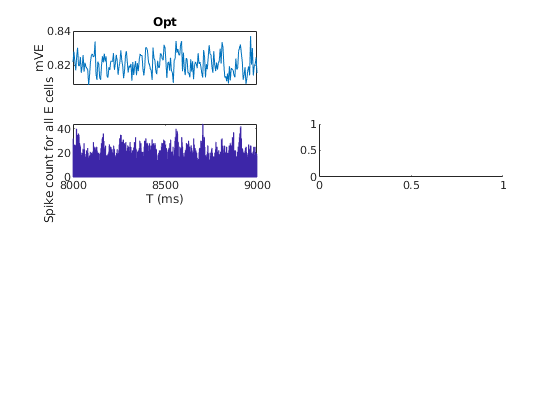

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),find(Opt & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

subplot 424

hist(SpE(ismember(SpE(:,1),find(find(Worst & MidHCE))),2),0:1:T)

Error using  & 
Matrix dimensions must agree.

xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

subplot 427
hist(SpE(ismember(SpE(:,1),find(Nor & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
xlim(ShowWin)

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

Plot Spatial maps: Plot

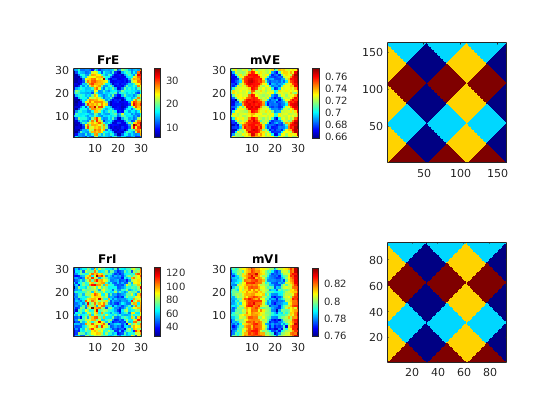

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


toc

Elapsed time is 59.496437 seconds.


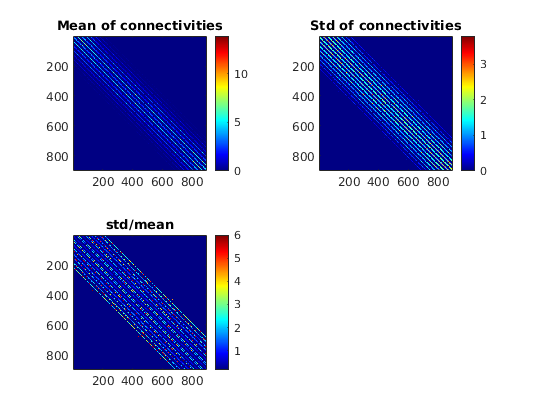

C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
L6E_Pixel = zeros(size(mVEPixVec));
L6I_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

EPixRange = [0 30];
IPixRange = [10 100]

IPixRange =     10   100



figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)

FrEPixMat_MF =    20.5894   28.6233   24.7044   24.4335   25.9186   27.0718   16.8385   14.3039    8.7136   14.0720   13.4965    1.6866    2.5922    6.2265   12.2535   13.4334   16.3352   18.1672   20.0336   17.0808   15.7901   25.9578   22.8523   22.7247   24.5900   16.0287    3.2829   -8.2080  -25.1141  -23.1537
   10.3041   12.8120   20.4999   24.1389   19.3841   14.2227   12.1852   11.5583   16.1184   19.3508   20.2114   16.7655   10.4849    5.9647   12.2977   16.3830   14.8437   18.6514   17.1043    9.6750   13.3364   14.5462   19.6530   20.3058   20.1605   15.0875   11.8916    3.4202    5.9077   -3.9696
    4.6333    5.7661   10.2214   15.3590   16.0993   18.5229   17.1192   16.5171   22.9037   22.6760   23.4623   24.3546   16.9019    9.9964    9.5165   15.0711   16.5141   13.6012    5.0266    6.7450    7.0961    4.8011   13.2036   17.6318   19.6574   14.5872   17.1099   17.9345   19.7436    8.2013
   -2.5843    3.2181    8.7140    7.9188   18.2919   15.7621   19.5004   28.8332  

imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    48.6951   69.7879   72.9806   71.9182   74.3799   79.7038   81.3995   76.0732   54.2942   82.8829   77.5668   54.0731   56.9500   73.3259   60.9656   66.0837   54.1399   61.9122   75.6751   54.0343   62.0538   80.6053   57.9754   67.8661   56.8540   62.5543   59.3880   44.2890   35.6139   78.0605
   42.5000   51.9005   70.8384   72.1385   74.9627   64.7650   70.6150   64.1394   73.1975   99.8984   85.3561   70.0523   51.7636   67.1963   56.1914   66.1540   52.2472   61.5967   54.9046   47.7904   48.9474   50.4493   71.6291   78.4886   55.1130   64.3623   59.1479   52.8000   58.3410   68.9692
   37.1127   47.4017   46.8463   70.1481   80.9925   60.5636   62.0235   78.3127   93.9313   91.6061   83.0885   81.5223   77.9477   71.6599   81.5469   63.5519   61.4276   70.8161   34.1369   53.9134   40.3135   44.1721   52.4276   72.8071   66.8554   64.6614   74.4880   58.4189   97.3015   72.9675
   33.8770   54.0477   51.7245   59.7065   69.7324   63.2994   81.0273  104.1428  

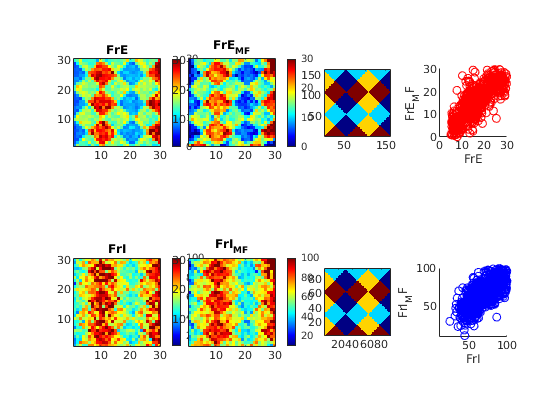

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?